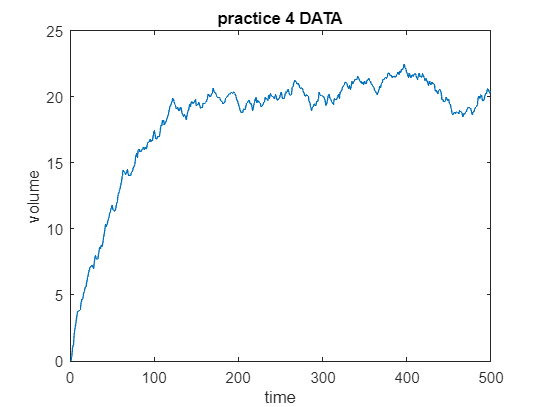

% Data generation
rng(5) % Inizialize random seed (for repetitibility)
T=0.2; % Sample time
kv=0.1;kb=2; % parameters for data generation
A=-kv;B=kb;sys=ss(A,B,1,0); % continuous system sys:dx=A·x+B·u
% y=1·x+0·u
% y=x=V=volume (Output = State variable)
% u=v_b (Input variable)
dsys=c2d(sys,T); % it converts to discrete system
[nd,dd]=tfdata(dsys,'v'); % it returns numerator and denominator
% as vectors
b=nd(2);a=-dd(2); % x(k)=a·x(k-1)+b·u(k)
N=500; % Number of input/output patterns
y=zeros(N,1); % it inizializes vector y (ouputs)
u=ones(N,1); % it inizializes vector u (inputs)
sigma=0.2; % Deviation of the white noise
for k=2:N % We obtain the data adding WHITE NOISE
y(k)=a*y(k-1)+b*u(k-1)+sigma*randn(1);
end
data=[u y];
save data data % Save data for future calculations
plot(y) % Plot the data generated
title('practice 4 DATA')
xlabel('time')
ylabel('volume')

% Non-Recursive Least Squares
Y = y(2:N); % column matrix Y
C = [y(1:N-1) u(1:N-1)]; % matrix C
J = @(x)(Y-C*x)'*(Y-C*x); % performance index
theta_est_3 = (C'*C)\C'*Y; % non-recursive least squares formula
sigma = J(theta_est_3)/(N-2); % estimation of noise variance
sigmab = sigma; % saving variance for 2.d
Cov_mat = sigma * (C'*C)'; % covariance matrix of the parameter estimators
std_error = sqrt(diag(Cov_mat)); % standard errors

% Recursive Least Squares
theta_est_rec = zeros(2, 1); % Assuming theta has 2 parameters
P = eye(2); % Initial error covariance matrix
for i = 3:N-1
    c = [y(i) u(i)]';
    D = 1 + c'*P*c; % Denominator
    K = P*c/D;
    theta_est_rec = theta_est_rec + K * (y(i+1) - c'*theta_est_rec);
    P = P - P * c * c' * P / D;

    if i > 3 % To avoid division by zero
        sigma = J(theta_est_rec)/(i - 2);  
    end
end

theta_est_3 = (C'*C)\C'*Y %non-recursive least squares formula

theta_est_3 =     0.9818
    0.3710


%Confidence intervals
sigma2=J(theta_est)/(N-2); % estimation of noise variance
sigma2b = sigma2; % saving variance for 2.d
Cov_mat=sigma2*(C'*C)'; % covariance matrix of the parameters estimators
std_error=sqrt(diag(Cov_mat)); % standard errors

kv_est=(1-theta_est(1))/T; % point l estimation of kv using Euler approximation
lbkv=(1-theta_est(1)-std_error(1)*3)/T; % lower bound for 98% confidence interval for kv
ubkv=(1-theta_est(1)+std_error(1)*3)/T; % upper bound for 98% confidence interval for kv
% Exact determination of confidence interval for kb_est is too difficult
kb_est=theta_est(2)/T; % point estimation of kb using Euler approximation
lbkb=(theta_est(2)-std_error(2)*3)/T; % lower bound for 98% confidence interval for kb
ubkb=(theta_est(2)+std_error(2)*3)/T; % upper bound for 98% confidence interval for kb

sys_arx = arx([y,u],[1,1,0])

sys_arx =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.9818 z^-1                           
                                                   
  B(z) = 0.371                                     
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=0
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 95.43% (prediction focus)
FPE: 0.04074, MSE: 0.04025                       
 
Model Properties



[theta_est_ARX,theta_est_ARX_sd] = getpvec(sys_arx) %theta and standard deviation of theta

theta_est_ARX =    -0.9818
    0.3710


theta_est_ARX_sd =     0.0021
    0.0384


theta_est_ARX = abs(theta_est_ARX);
% Parameter nominal values and confidence interval
kv_est_ARX = (1 - theta_est_ARX(1)) / T;                     % point 1 estimation of kv using Euler approximation
lbkv_ARX = (1 - theta_est_ARX(1) - theta_est_ARX_sd(1)*3) / T;  % lower bound for 98% confidence interval for kv
ubkv_ARX = (1 - theta_est_ARX(1) + theta_est_ARX_sd(1)*3) / T;  % upper bound for 98% confidence interval for kv
% Exact determination of confidence interval for kb_est is too difficult
kb_est_ARX = theta_est_ARX(2) / T;                           % point estimation of kb using Euler approximation
lbkb_ARX = (theta_est_ARX(2) - theta_est_ARX_sd(2)*3) / T;      % lower bound for 98% confidence interval for kb
ubkb_ARX = (theta_est_ARX(2) + theta_est_ARX_sd(2)*3) / T;      % upper bound for 98% confidence interval for kb
Comparison = ["kv";"lbkv";"ubkv";"kb";"lbkb";"ubkb"];
Non_recursive = [kv_est;lbkv;ubkv;kb_est;lbkb;ubkb];
ARX = [kv_est_ARX;lbkv_ARX;ubkv_ARX;kb_est;lbkb_ARX;ubkb_ARX];
results = table(Comparison,Non_recursive,ARX)

results = 6×3 table
    Comparison    Non_recursive      ARX   
    __________    _____________    ________

      "kv"          0.090754       0.090754
      "lbkv"         -1259.8       0.059997
      "ubkv"            1260        0.12151
      "kb"            1.8548         1.8548
      "lbkb"         -65.504         1.2795
      "ubkb"          69.213         2.4301


Y=[y(2);y(3)];          %Y(3)
C=[y(1:2) u(1:2)];      %C(3)
P=inv(C'*C);            %P(3)
theta_est_rec=P*C'*Y;    %theta(3)
for i=3:N-1
 c=[y(i) u(i)];
 D=1+c*P*c'; %Denominator
 K=P*c'/D;
 theta_est_rec=theta_est_rec+K*(y(i+1)-c*theta_est_rec);
 P=P-P*c'*c*P/D;
end

kv_est_rec=-log(theta_est_rec(1))/T % point estimation of kv

kv_est_rec = 0.0916

kb_est_rec=kv_est_rec*theta_est_rec(2)/(1-exp(-kv_est_rec*T)) % kb

kb_est_rec = 1.8718

clear lbkb ubkb lbkv ubkv kb_est kv_est;
lbkb=zeros(N,1);
ubkb=zeros(N,1);
lbkv=zeros(N,1);
ubkv=zeros(N,1);
kb_est=zeros(N,1);
kv_est=zeros(N,1);
for i=3:N-1
    c=[y(i) u(i)];

    D=1+c*P*c'; %Denominator
    K=P*c'/D;
    theta_est_rec=theta_est_rec+K*(y(i+1)-c*theta_est_rec);
    P=P-P*c'*c*P/D;

    sigma2=J(theta_est_rec)/(i-2);  % estimation of noise variance
    Cov_mat=sigma2*P;               % covariance matrix
    std_error=sqrt(diag(Cov_mat));  % standard errors
    
    kv_est(i)=(1-theta_est_rec(1))/T;               % point estimation of kv
    lbkv(i)=(1-theta_est_rec(1)-std_error(1)*3)/T;  % lower bound for 98%
    ubkv(i)=(1-theta_est_rec(1)+std_error(1)*3)/T;  % upper bound for 98%
    kb_est(i)=theta_est_rec(2)/T;                   % point estimation of kb
    lbkb(i)=(theta_est_rec(2)-std_error(2)*3)/T;    % lower bound for 98%
    ubkb(i)=(theta_est_rec(2)+std_error(2)*3)/T;    % upper bound for 98%
end

load data data; % Read data
u = data(:,1); % it extracts inputs
y = data(:,2); % it extracts outputs 
N = size(data,1); % determine the number of points
T = 0.2; % Sample time

lbkb_ARX1=zeros(N,1);
ubkb_ARX1=zeros(N,1);
lbkv_ARX1=zeros(N,1);
ubkv_ARX1=zeros(N,1);
kv_est_ARX=zeros(N,1);
kb_est_ARX=zeros(N,1);
std_error_ARX = [];

estimator = recursiveARX([1 1 0]);

for k = 1:N
    [theta1,theta2,y_hat] = estimator(y(k),u(k));
    cov = estimator.ParameterCovariance;  % covariance matrix
 
    theta_ARX = [-theta1(2) theta2];          
    std_error_ARX = diag(sqrt(cov));

    kv_est_ARX(k) =(1-theta_ARX(1))/T;                     % Estimation of kv
    lbkv_ARX1(k) = (1-theta_ARX(1)-std_error_ARX(1)*3)/T;   % lower bound for 98%
    ubkv_ARX1(k) = (1-theta_ARX(1)+std_error_ARX(1)*3)/T;   % upper bound for 98%

    kb_est_ARX(k) = theta_ARX(2)/T;                      % Estimation of kb
    lbkb_ARX1(k) = (theta_ARX(2)-std_error_ARX(2)*3)/T;   % lower bound for 98%
    ubkb_ARX1(k) = (theta_ARX(2)+std_error_ARX(2)*3)/T;   % upper bound for 98%
end

kv_est_ARX1=-log(theta_ARX(1))/T % point estimation of kv

kv_est_ARX1 = 0.0881

kb_est_ARX1=kv_est_ARX1*theta_ARX(2)/(1-exp(-kv_est_ARX1*T)) % kb

kb_est_ARX1 = 1.8056

Comparison = ["kv";"lbkv";"ubkv";"kb";"lbkb";"ubkb"];
recursive = [kv_est_rec;lbkv(N-2);ubkv(N-2);kb_est_rec;lbkb(N-2);ubkb(N-2)];
recARX = [kv_est_ARX1;lbkv_ARX1(N-2);ubkv_ARX1(N-2);kb_est_ARX1;lbkb_ARX1(N-2);ubkb_ARX1(N-2)];
results = table(Comparison,recursive,recARX)

results = 6×3 table
    Comparison    recursive     recARX  
    __________    _________    _________

      "kv"        0.091588      0.088148
      "lbkv"      0.067184     -0.062885
      "ubkv"       0.11148       0.23784
      "kb"          1.8718        1.8056
      "lbkb"        1.4119        -1.018
      "ubkb"        2.2413        4.5994


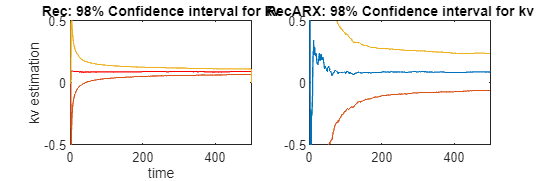

figure('Position',[0 0 1200 400])
subplot(1,2,1)
plot(kv_est,'r'), hold on;
plot(lbkv);
plot(ubkv);
axis([0 N -0.5 0.5]);
title('Rec: 98% Confidence interval for kv');
xlabel('time');
ylabel('kv estimation');
subplot(1,2,2)
plot(kv_est_ARX), hold on
plot(lbkv_ARX1)
plot(ubkv_ARX1)
title('RecARX: 98% Confidence interval for kv')
axis([0 N -0.5 0.5]);

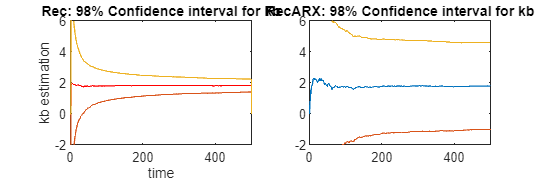

figure('Position',[0 0 1200 400])
subplot(1,2,1)
plot(kb_est,'r'), hold on;
plot(lbkb);
plot(ubkb);
axis([0 N -2 6]);
title('Rec: 98% Confidence interval for kb');
xlabel('time');
ylabel('kb estimation');
subplot(1,2,2)
plot(kb_est_ARX), hold on
plot(lbkb_ARX1)
plot(ubkb_ARX1)
title('RecARX: 98% Confidence interval for kb')
axis([0 N -2 6]);

% Parameter estimation
load data data                    % it reads data
u = data(:, 1);               % it extracts inputs
y = data(:, 2);               % it extracts outputs
N = 500;
T = 0.2;

Y = [y(2); y(3)];             % Y(3)
C = [y(1: 2) u(1: 2)];        % C(3)
P = inv(C' * C);              % P(3)
theta_est_kal = P * C' * Y;   % theta(3)

sigma2=sigma2b  % estimation of noise variance from 2.b

sigma2 = 0.0404


lbkb_kal=zeros(N, 1);
ubkb_kal=zeros(N, 1);
lbkv_kal=zeros(N, 1);
ubkv_kal=zeros(N, 1);
kbest_kal=zeros(N, 1);
kvest_kal=zeros(N, 1);

J = @(x) (Y-C*x)'*(Y-C*x);               % performance index
for i=3:N-1
    c=[y(i) u(i)]';         
    L=P*c/(sigma2+c'*P*c);
    theta_est_kal=theta_est_kal+L*(y(i+1)-transpose(c)*theta_est_kal);
    P=(eye(2)-L*transpose(c))*P;
        
    sigma2=J(theta_est_kal)/(i-2);      % estimation of noise variance
    Cov_mat=sigma2*P;                   % covariance matrix
    std_error=sqrt(diag(Cov_mat));      % standard errors

    kv_est_kal(i)=(1-theta_est_kal(1))/T;   % point estimation of kv
    lbkv_kal(i)=(1-theta_est_kal(1)-std_error(1)*3)/T;  % lower bound for 98%
    ubkv_kal(i)=(1-theta_est_kal(1)+std_error(1)*3)/T;  % upper bound for 98%

    kb_est_kal(i)=theta_est_kal(2)/T;       % point estimation of kb
    lbkb_kal(i)=(theta_est_kal(2)-std_error(2)*3)/T;    % lower bound for 98%
    ubkb_kal(i)=(theta_est_kal(2)+std_error(2)*3)/T;    % upper bound for 98%
end
kv_est_Kal1=-log(theta_est_kal(1))/T    % point estimation of kv

kv_est_Kal1 = 0.1006

kb_est_Kal1=kv_est_Kal1*theta_est_kal(2)/(1-exp(-kv_est_Kal1*T)) % kb

kb_est_Kal1 = 2.0596

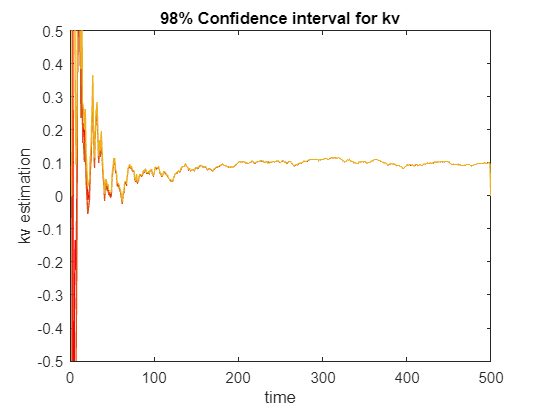

figure
plot(kv_est_kal,'r');
hold on;
plot(lbkv_kal);
plot(ubkv_kal);
axis([0 N -0.5 0.5]);
title('98% Confidence interval for kv');
xlabel('time');
ylabel('kv estimation');

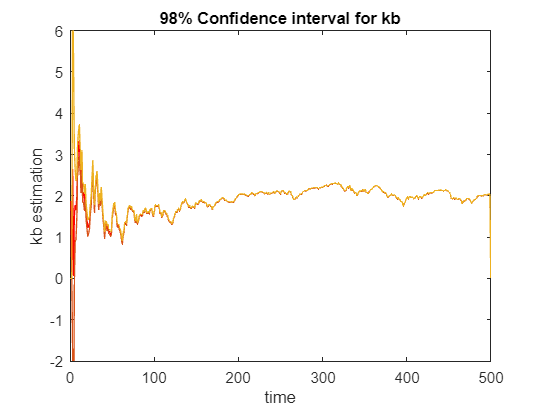

figure
plot(kb_est_kal,'r');
hold on;
plot(lbkb_kal);
plot(ubkb_kal);
axis([0 N -2 6]);
title('98% Confidence interval for kb');
xlabel('time');
ylabel('kb estimation');

Conclusion

• In this activity we have seen how using a mathematical solution like “quadprog”, use Ricatti method,

Ricatti method with steady state, LMI and dynamic programming methods give use the same

solution.

• We can see how including upper and lower bounds affects our system and improve it.